clear;clc;

% load parameters
par_scg = importdata('par_scg_clock.txt');
par_scg = par_scg.data;
n_E = par_scg(3);
n_I = par_scg(4);

par_clock = load('par_clock.csv');
n_clock = 12;

% initial values
y0 = zeros(n_E+n_I+n_clock+2, 1);
y0(n_clock+1) = 1;

tmax = 1000;
tspan = 0:0.1:tmax;

t_V_0 = 500;
delta_t = 6;

y = zeros(length(tspan), n_E+n_I+n_clock+2, 5);
parfor i = 1:4
    [~, y(:, :, i)] = ode45(@ODE_SCG_CLOCK, tspan, y0, [], par_clock, par_scg, t_V_0 + delta_t * (i - 1));
end

Starting parallel pool (parpool) using the 'Processes' profile ...
Connected to the parallel pool (number of workers: 12).


par_scg(9) = 100000;
[~, y(:, :, 5)] = ode45(@ODE_SCG_CLOCK, tspan, y0, [], par_clock, par_scg, t_V_0);
y = real(y);

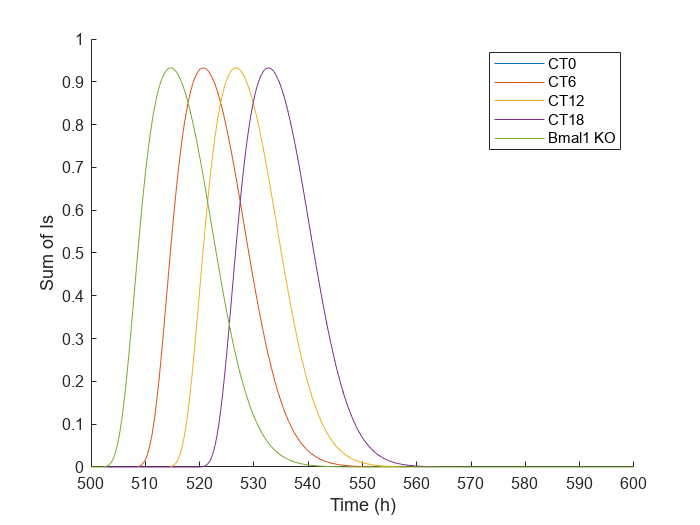

% plot sum of Is
figure; hold on;
I_tot = zeros(length(tspan), 5);
for i = 1:5
    for j = (n_E+n_clock+1):(n_E+n_I+n_clock)
        I_tot(:, i) = I_tot(:, i) + y(:, j, i);
    end
    plot(tspan, I_tot(:, i));
end
xlim([500 600]);
xlabel('Time (h)'); ylabel('Sum of Is');
legend('CT0', 'CT6', 'CT12', 'CT18', 'Bmal1 KO');
hold off;

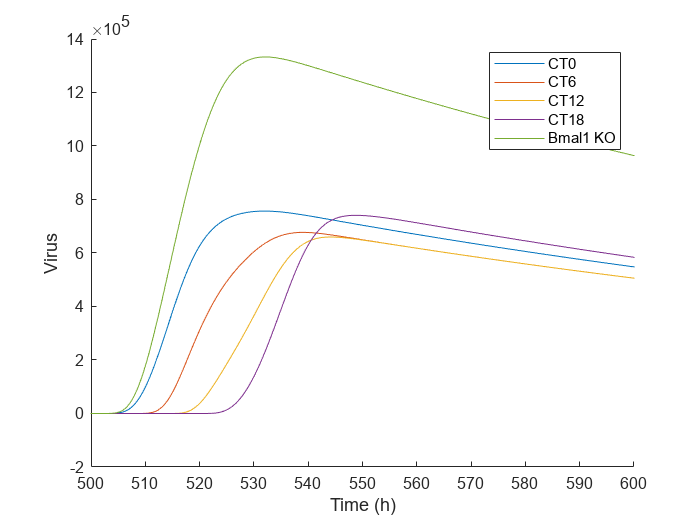


% Plot total virus RNA (Bioluminescence)
figure; hold on;
for i = 1:5
    plot(tspan, y(:, n_E+n_I+n_clock+1, i));
end
xlim([500 600]);
xlabel('Time (h)'); ylabel('Virus');
legend('CT0', 'CT6', 'CT12', 'CT18', 'Bmal1 KO');
hold off;

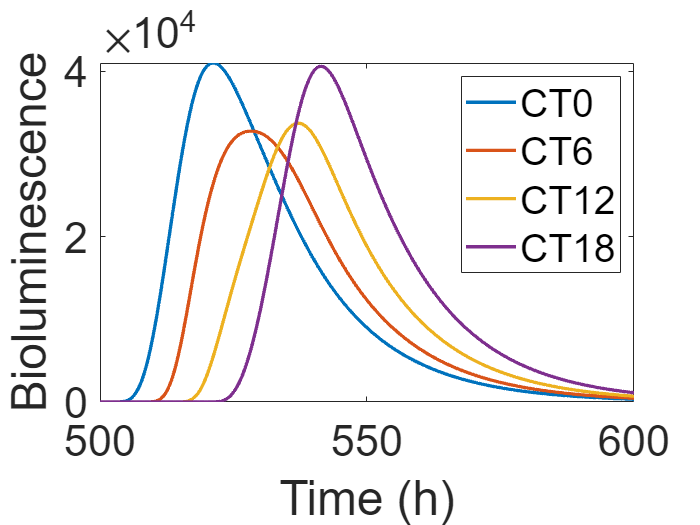

% Plot bioluminescence (B)
figure; hold on; set(gca,'Fontsize',26); box on;
for i = 1:4
    plot(tspan, y(:, n_E+n_I+n_clock+2, i), 'LineWidth', 2);
end
xlim([500 600]);
xlabel('Time (h)'); ylabel('Bioluminescence');
legend('CT0', 'CT6', 'CT12', 'CT18');
hold off;

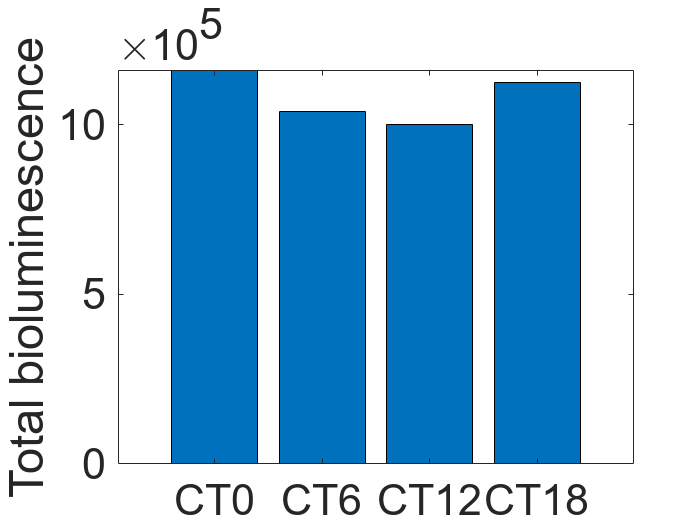

% calculate some related values of boiluminescence curve
biolu_tot = zeros(1, 5);
half_t = zeros(2, 5); % left, right

for i = 1:5
    B = y(:, n_E+n_I+n_clock+2, i);
    [peak_var, peak_idx] = max(B);
    B_left = B(1:peak_idx);
    B_right = B(peak_idx+1:end);

%     biolu_tot(i) = trapz(tspan(1:peak_idx), B_left) / trapz(tspan, B);
    biolu_tot(i) = trapz(tspan, B);
    [~, half_t(1, i)] = min(abs(B_left - peak_var / 2));
    [~, half_t(2, i)] = min(abs(B_right - peak_var / 2));
end

bar_name = categorical({'CT0', 'CT6', 'CT12', 'CT18'});
bar_name = reordercats(bar_name, {'CT0', 'CT6', 'CT12', 'CT18'});

bar(bar_name, biolu_tot(1:4)); ylabel('Total bioluminescence');
set(gca,'Fontsize',26); box on;

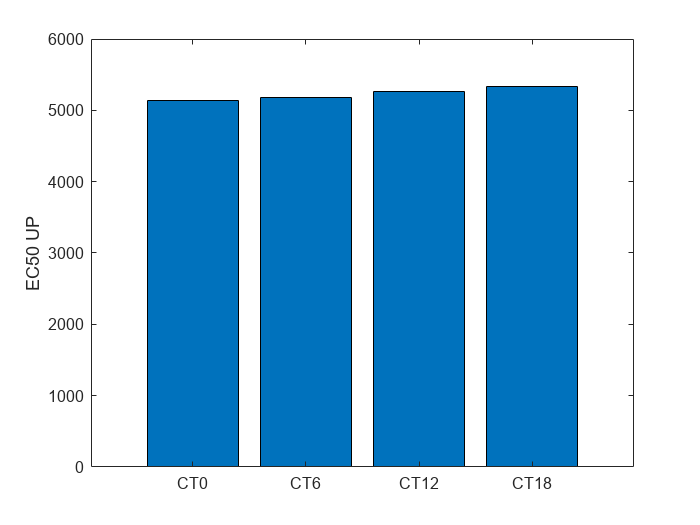

bar(bar_name, half_t(1, 1:4)); ylabel('EC50 UP');

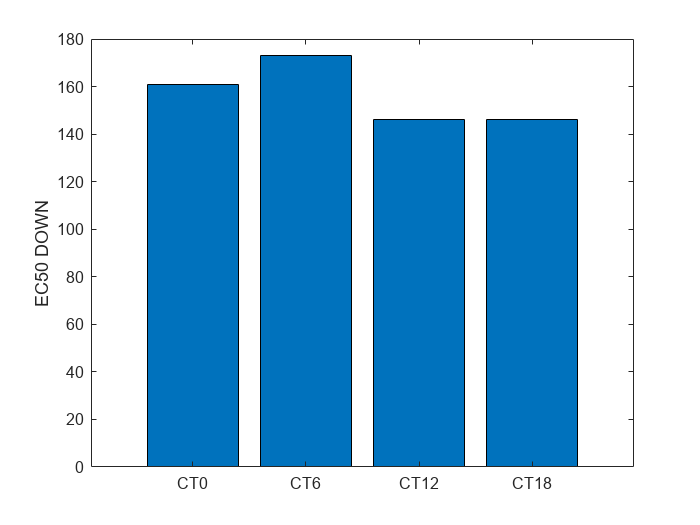

bar(bar_name, half_t(2, 1:4)); ylabel('EC50 DOWN');

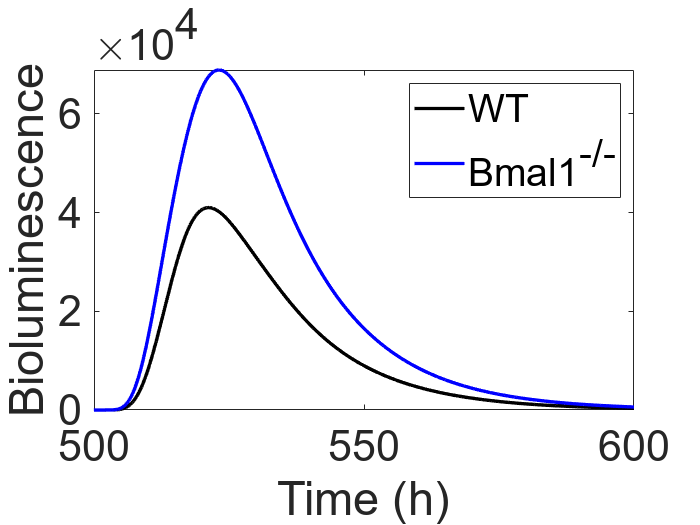

% Plot bioluminescence (B) clock ko
figure; hold on; set(gca,'Fontsize',26); box on;
plot(tspan, y(:, n_E+n_I+n_clock+2, 1), 'LineWidth', 2, 'Color', 'k');
plot(tspan, y(:, n_E+n_I+n_clock+2, 5), 'LineWidth', 2, 'Color', 'b');
xlim([500 600]);
xlabel('Time (h)'); ylabel('Bioluminescence');
legend('WT', 'Bmal1^{-/-}');
hold off;